setup() ;

## Part 1.1: convolution

## Part 1.1.1: convolution by a single filter

Load an image and convert it to gray scale and single precision

x = im2single(rgb2gray(imread('data/ray.jpg'))) ;

% Define a filter
w = single([
   0 -1  0
  -1  4 -1
   0 -1  0]) ;

% Apply the filter to the image
y = vl_nnconv(x, w, [], 'Pad', 1) ;

Visualize the results

figure(11) ; clf ; colormap gray ;
set(gcf, 'name', 'Part 1.1: convolution') ;

subplot(2,2,1) ;
imagesc(x) ;
axis off image ;
title('Input image x') ;

subplot(2,2,2) ;
imagesc(w) ;
axis off image ;
title('Filter w') ;

subplot(2,2,3) ;
imagesc(y) ;
size(y)

ans =    150   200


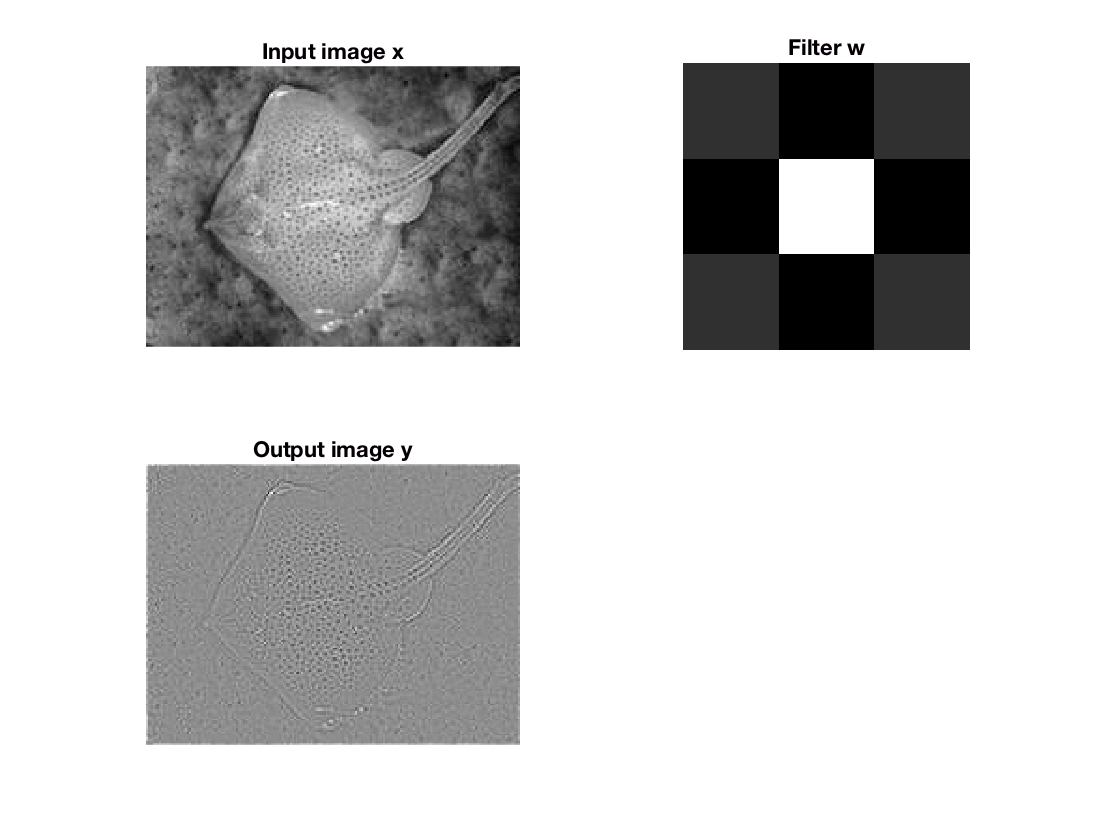

axis off image ;
title('Output image y') ;

## Part 1.1.2: convolution by a bank of filters

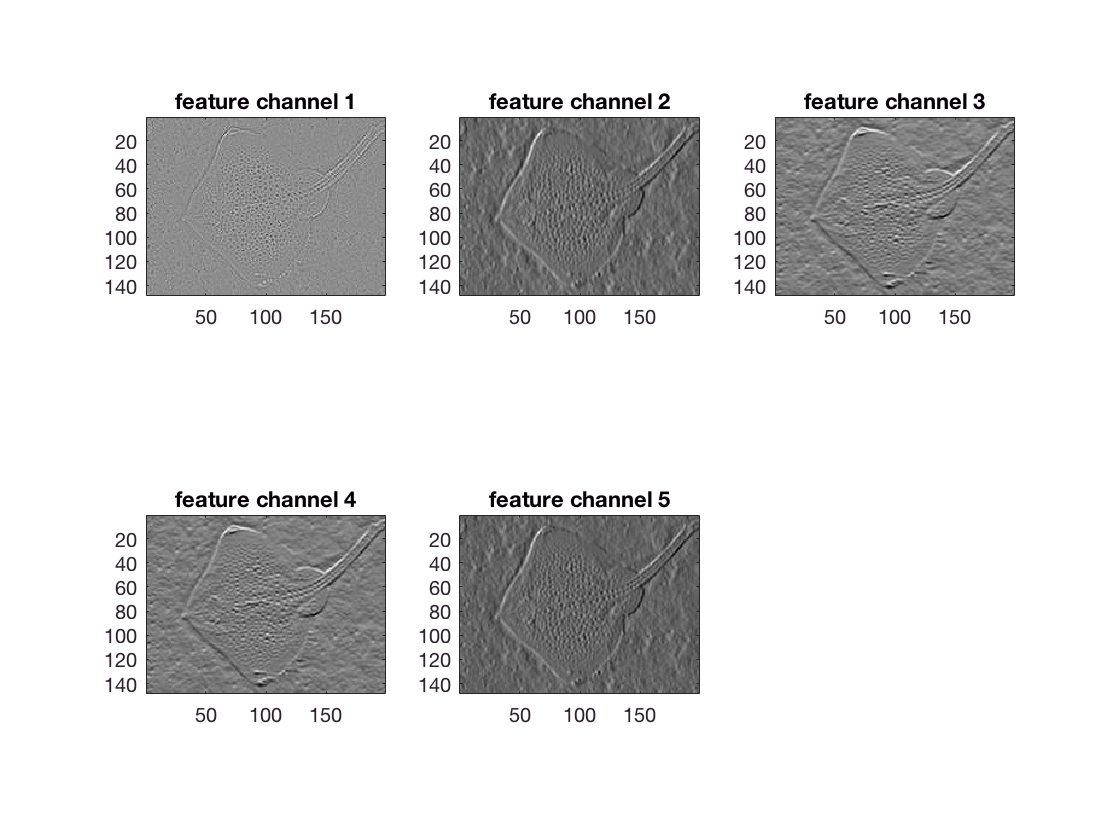

% Concatenate three filters in a bank
w1 = single([
   0 -1  0
  -1  4 -1
   0 -1  0]) ;

w2 = single([
  -1 0 +1
  -1 0 +1
  -1 0 +1]) ;

w3 = single([
  -1 -1 -1
   0  0  0
  +1 +1 +1]) ;

sobely = single([
  -1 -2 -1
   0  0  0
  +1 +2 +1]) ;

sobelx = single([
  -1 0 +1
  -2 0 +2
  -1 0 +1]) ;
    

wbank = cat(4, w1, w2, w3, sobely, sobelx) ;

% Apply convolution
y = vl_nnconv(x, wbank, []) ;

% Show feature channels
figure(12) ; clf('reset') ;
set(gcf, 'name', 'Part 1.1.2: channels') ;
colormap gray ;
showFeatureChannels(y) ;

size(y)

ans =    148   198     5


## Part 1.1.3: convolving a batch of images

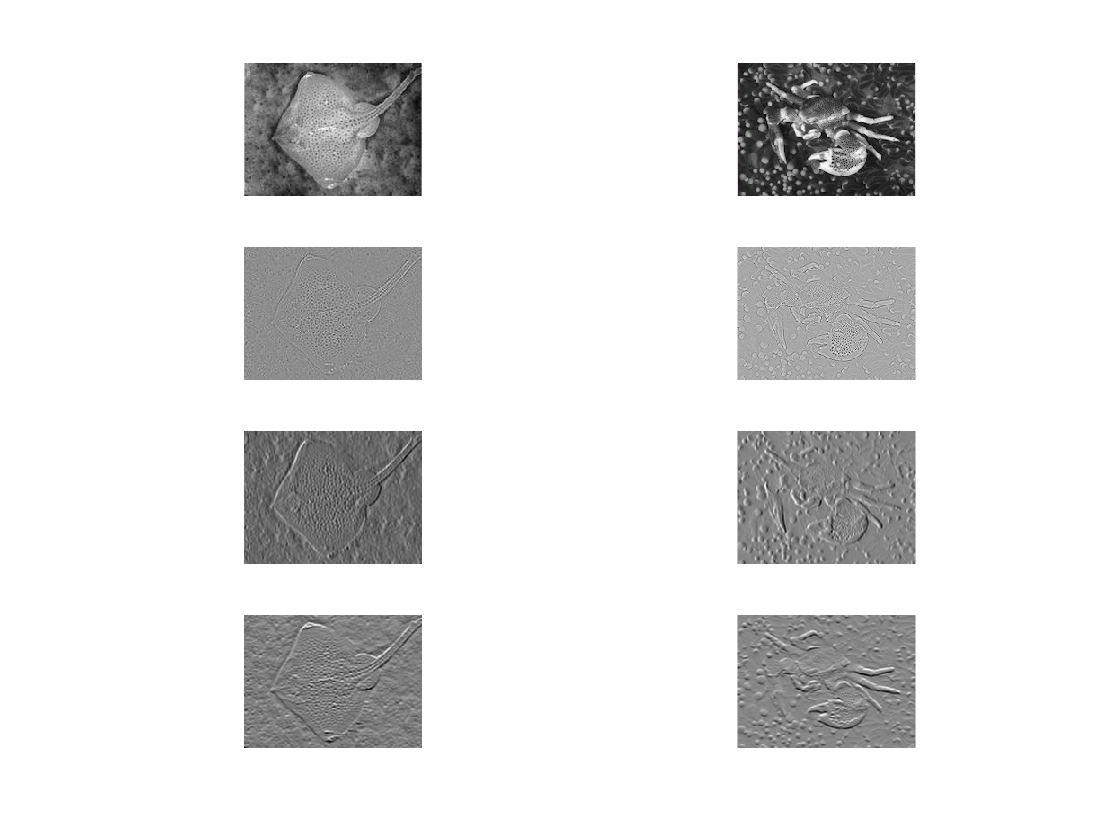

x1 = im2single(rgb2gray(imread('data/ray.jpg'))) ;
x2 = im2single(rgb2gray(imread('data/crab.jpg'))) ;
x = cat(4, x1, x2) ;

y = vl_nnconv(x, wbank, []) ;

figure(13) ; clf('reset') ; colormap gray ;
set(gcf, 'name', 'Part 1.1.3: filtering a batch') ;

subplot(4,2,1) ; imagesc(x1) ; axis off image ;
subplot(4,2,3) ; imagesc(y(:,:,1,1)) ; axis off image ;
subplot(4,2,5) ; imagesc(y(:,:,2,1)) ; axis off image ;
subplot(4,2,7) ; imagesc(y(:,:,3,1)) ; axis off image ;

subplot(4,2,2) ; imagesc(x2) ; axis off image ;
subplot(4,2,4) ; imagesc(y(:,:,1,2)) ; axis off image ;
subplot(4,2,6) ; imagesc(y(:,:,2,2)) ; axis off image ;
subplot(4,2,8) ; imagesc(y(:,:,3,2)) ; axis off image ;

## visualize the results

## Part 1.2: non-linear activation functions (ReLU)

## Part 1.2.1: Laplacian and ReLU

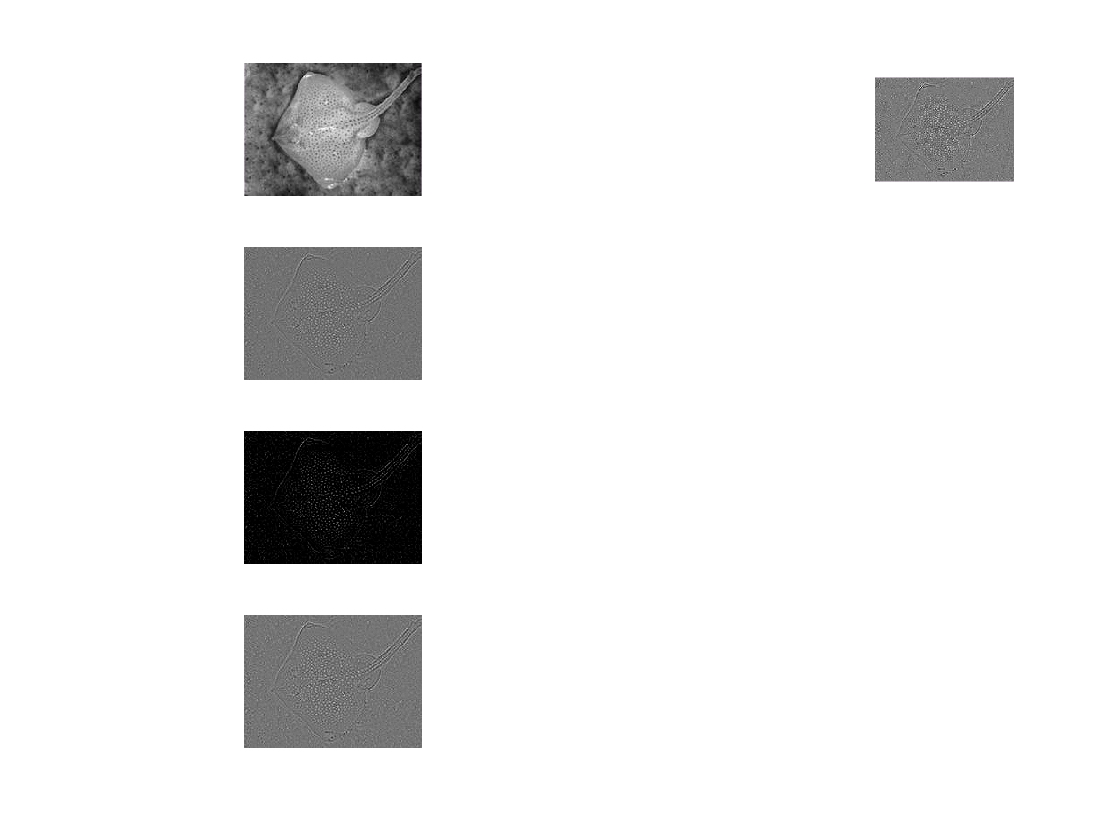

x = im2single(rgb2gray(imread('data/ray.jpg'))) ;

% Convolve with the negated Laplacian
y = vl_nnconv(x, - w, []) ;

% Apply the ReLU operator
z = vl_nnrelu(y) ;
a = vl_nnsigmoid(y);
b = tanh(y);

figure(13) ; clf('reset') ; colormap gray ;
set(gcf, 'name', 'Part 1.2.1: filtering a batch') ;

subplot(4,2,1) ; imagesc(x) ; axis off image ;
subplot(4,2,3) ; imagesc(y(:,:,1,1)) ; axis off image ;
subplot(4,2,5) ; imagesc(z(:,:,1,1)) ; axis off image ;
subplot(4,2,7) ; imagesc(a(:,:,1,1)) ; axis off image ;
subplot(4,5,5) ; imagesc(b(:,:,1,1)) ; axis off image ;

## visualize the results

## Part 1.2.2: effect of adding a bias

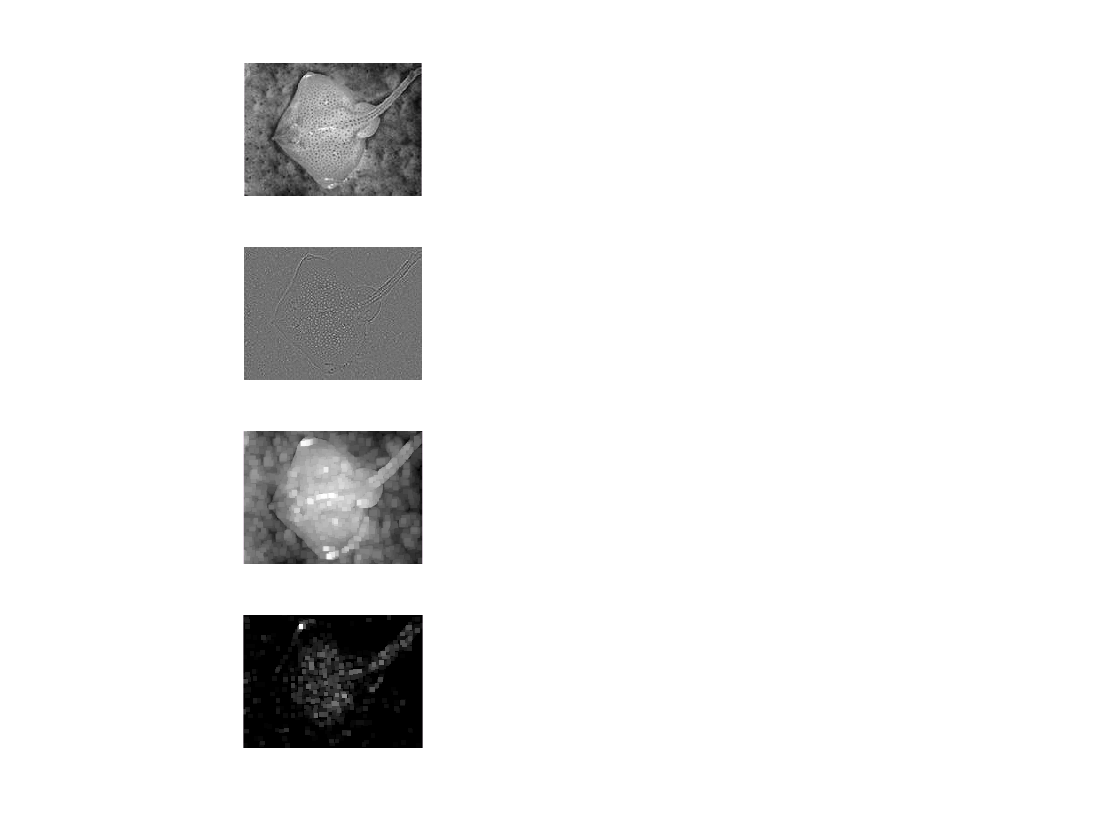

bias = single(- 0.2) ;
y = vl_nnconv(x, - w, bias) ;
z = vl_nnrelu(y) ;

my = vl_nnpool(y, 5, 'method', 'max');
mx = vl_nnpool(x, 5, 'method', 'max');

figure(14) ; clf('reset') ; colormap gray ;
set(gcf, 'name', 'Part 1.2.2') ;

subplot(4,2,1) ; imagesc(x) ; axis off image ;
subplot(4,2,3) ; imagesc(y(:,:,1,1)) ; axis off image ;
subplot(4,2,5) ; imagesc(z(:,:,1,1)) ; axis off image ;
subplot(4,2,7) ; imagesc(my(:,:,1,1)) ; axis off image ;
subplot(4,2,5); imagesc(mx(:,:,1,1)); axis off image;

## visualize the results